**2 Boyutta Vektörlerin Dönüşümü ile ilgili MATLAB Uygulamaları (Robotics Toolbox for MATLAB)**

Peter Coke fonksiyonları kullanılacaktır.

- **plotvol:** 2 veya 3 boyutta çizim için sınırları belirleme.

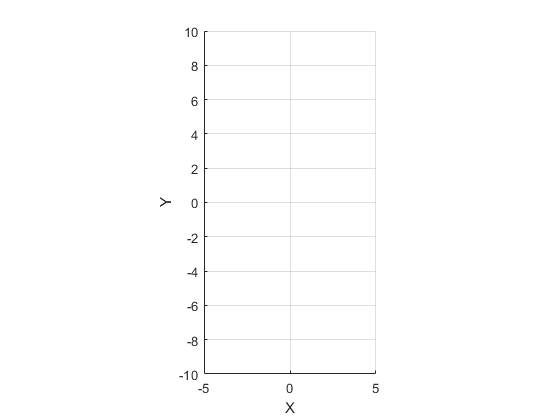

plotvol([-5 5 -10 10])

- **rot2**: 2 boyutta rotasyon matrisini  verir

rot2(pi/2) % direkt radyan olarak kabul eder.

ans =     0.0000   -1.0000
    1.0000    0.0000


rot2(90, 'deg') % dereceyi radayana çevirir.

ans =     0.0000   -1.0000
    1.0000    0.0000


- **transl2:** translational homogeneus transform

- 2  boyutta öteleme için homojen dönüşüm matrisini verir.

transl2(5,8)

ans =      1     0     5
     0     1     8
     0     0     1


- **trot2:** rational homogeneus transform

- 2 boyutta dönüşüm için homojen dönüşüm matrisini verir.

trot2(pi/2)

ans =     0.0000   -1.0000         0
    1.0000    0.0000         0
         0         0    1.0000


trot2(90, 'deg')

ans =     0.0000   -1.0000         0
    1.0000    0.0000         0
         0         0    1.0000


trplot2: plot a 2D coordinate frame

2 boyutta koordinat sistemi çizer.

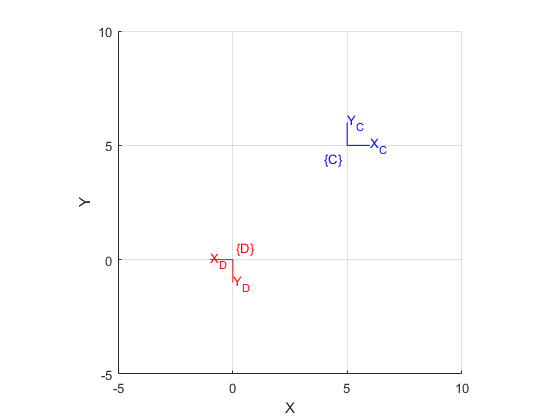

plotvol([-5 10 -5 10])
trplot2(transl2(5,5), 'frame','C','color','b')
trplot2(rot2(180, 'deg'), 'frame','D','color','r')

- **plot_point: **Noktayı çizer

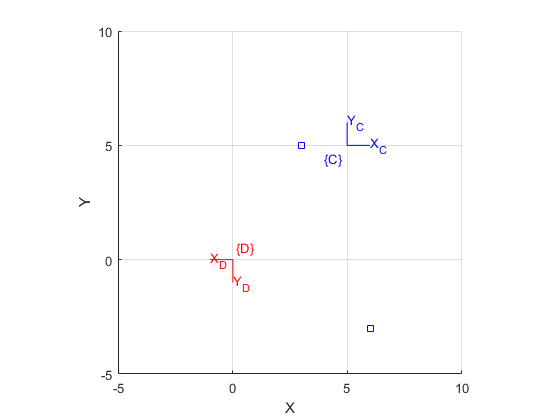

plot_point([3 6 ; 5 -3])

- **e2h:** euler -> homojen

P = [ 3 ; 5]

P =      3
     5


Ph = e2h(P)

Ph =      3
     5
     1


- **h2e:** homojen -> euler

P2 = h2e(Ph)

P2 =      3
     5


**ÖRNEK:**A koordinat sistemi önce (5,5) öteleme sonra 270 derece döndürülerek elde edilmiştir. P noktası A koordinat sistemine göre (4,7) olarak verilmiştir. P noktasını dünya koordinat sistemine göre tanımlayınız.

clf
plotvol([0 15 -5 10])

A = transl2(5,5) * trot2(270, 'deg') % dünya koordinat sistemine göre A koordinat sistemi

A =    -0.0000    1.0000    5.0000
   -1.0000   -0.0000    5.0000
         0         0    1.0000


PA = [4 7]' % A2ya göre P noktası

PA =      4
     7


PO = A * e2h(PA) % dünya koordinat sistemine göre P noktası

PO =    12.0000
    1.0000
    1.0000


trplot2(A,'frame','A','color','r')
plot_point(PA,'+') % böyle çizdirirsek (4,7) noktasını dünya koordinat sistemine göre çizer
plot_point(e2h(PO),'*') % A'ya göre (4,7) olan noktanın dünya koordinat sisteminde nereye denk geldiğini bulup çizdirdiğimizde doğru sonuç olur. 
% Çünkü P noktasının yeri aynı ama koordinat sistemlerine göre konumları farklı

**ÖRNEK: **S noktası dünya koordinat siistemine göre (2,4) olarak tanımlanmıştır. S noktasını A koordinat sistemine göre tanımlayınız.

SO = [2 4]'

SO =      2
     4


SA = inv(A) * e2h(SO)

SA =     1.0000
   -3.0000
    1.0000


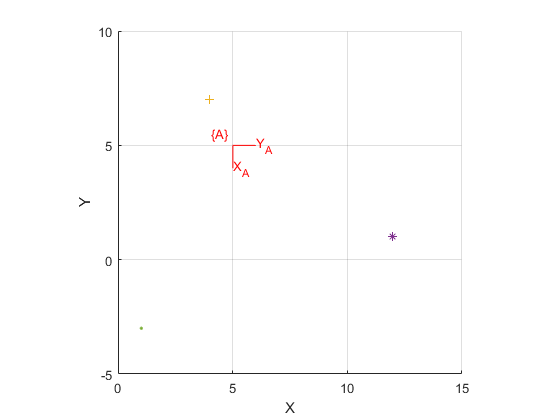

plot_point(h2e(SA)+3,'.')